# LAB 8: FREQUENCY DOMAIN IDENTIFICATION OF QNET DC MOTOR

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Hongtao Xu';
Students.ID = '260773785';
%---------------------------------------

## **0. Objectives**

In this lab, we will use frequency analysis to identify the transfer function of the Virtual Motor. To initiate a connection with the virtual motor, run the following:

Motor = VirtualMotor();

## **1. Frequency Response Analysis**

When a cosine wave $x(t) = M_x \cos(\omega t)$ is injected into a linear system, the system will respond with the same frequency $\omega$, a certain magnitude $M_x$ and a certain phase angle relative to the input $\phi$. The steady-state system output can be written as $y(t) = M_y \cos(\omega t + \phi)$.

If $G(j \omega)$ is the frequency response of this system, we define the magnitude and phase at $\omega$ by:


$$M(\omega) = \frac{M_y}{M_x} = || G(j \omega) ||$$



$$\phi(\omega) = \angle G(j \omega)$$


## *1.1 Bode plot*

The Bode plot presents the magnitude and the phase shift between the input and output at each frequency. It is possible to draw a `point-by-point` Bode plot by injecting a cosine wave with a known frequency, once at a time, and measuring the magnitude and phase shift of the output after it reaches its steady-state.

In a bode plot the magnitude is represented in a logarithmic scale in decibels (db).


$$M_{db}(\omega) = 20 \log(M(\omega))$$


The phase at each frequency can be found by measuring the temporal delay between the output and the input when the input is a cosine wave. Another way to measure the phase shift is through the Lissajous method. A Lissajous curve (an ellipsoid) is found when we try to plot the output in function of the input (XY plot). In fact, we can show that at a frequency $\omega$


$$\cos(\phi) = \frac{y^*}{M_y}$$


Where $y^*$ is the value of the output $y$ when the input $x$ is at the maximum $M_x$.

An illustration of using the Lissajous method (taken from Wikipedia) is shown below:

<<fig_lab08_lissajousphase.png>>

## *Question 1 (2.5 mark)*

- Define the following transfer function in `MATLAB`


$$G(s) = \frac{s + 4}{s^2+s+1}$$


G = tf([1 4],[1 1 1])


G =
 
     s + 4
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



- Plot the bode graph of this system. (Hint: help `bode`)

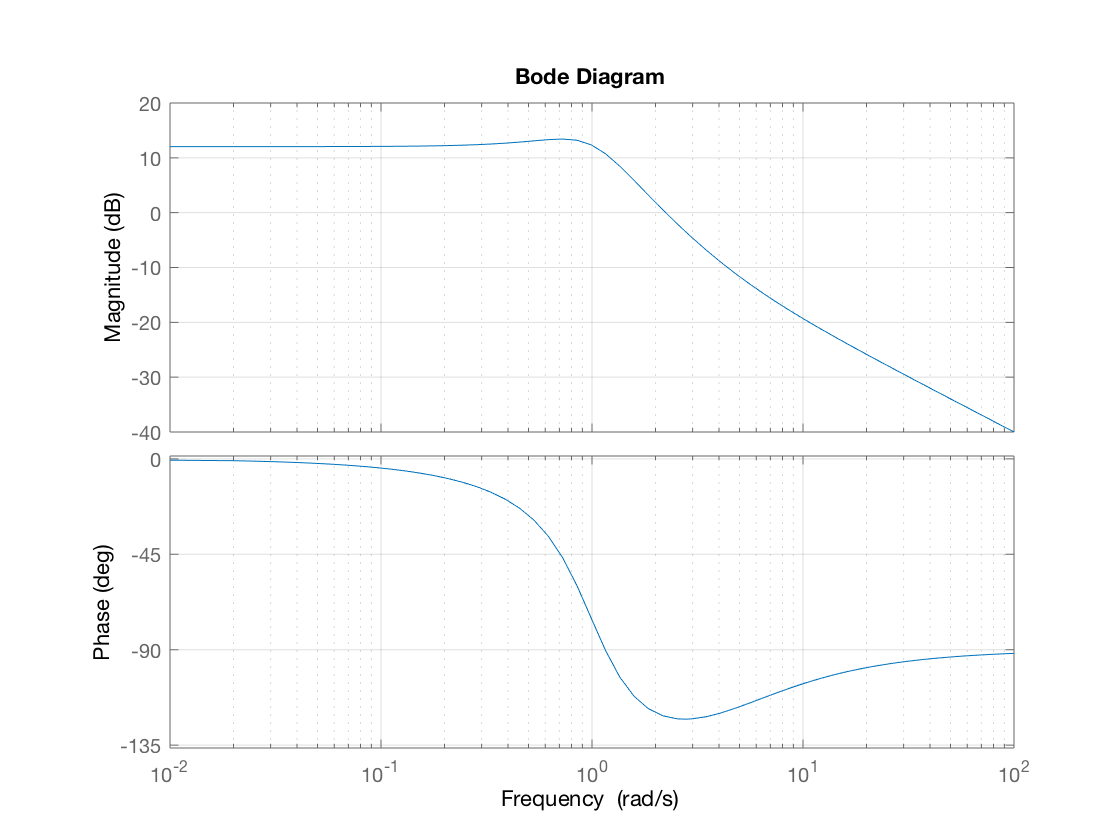

figure(1); clf;
% Plot Bode here
bode(G)
grid on

- Consider the following signal:

rng(datetime('now').Year*randi([1,20],1))
Freq = round(0.1+rand(1), 2);
t = 0:0.01:round(10/Freq);
x = cos(2*pi*Freq*t);

Using `lsim` simulate the output $y(t)$ representing the response of the system $G$ to the signal $x(t)$.

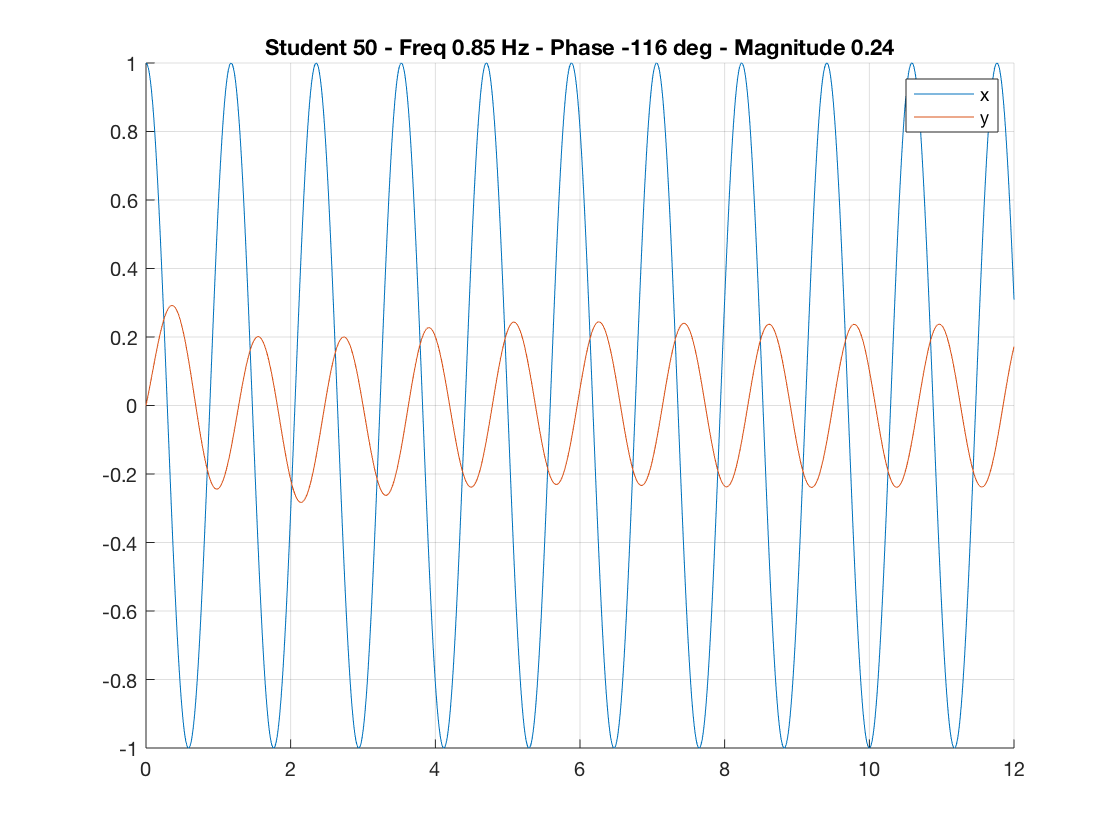

y = lsim(G,x,t);

figure(2); clf;
title(sprintf('Student %d - Freq %3.2f Hz - Phase %+03d deg - Magnitude %4.2f',...
    Students.ID(1), Freq, round(180*angle(evalfr(G, 2*pi*Freq*1i))/pi), abs(evalfr(G, 2*pi*Freq*1i))));
hold on
plot(t, x)
plot(t, y)
grid on
legend('x', 'y')

- Plot $y(t)$ in function of $x(t)$.

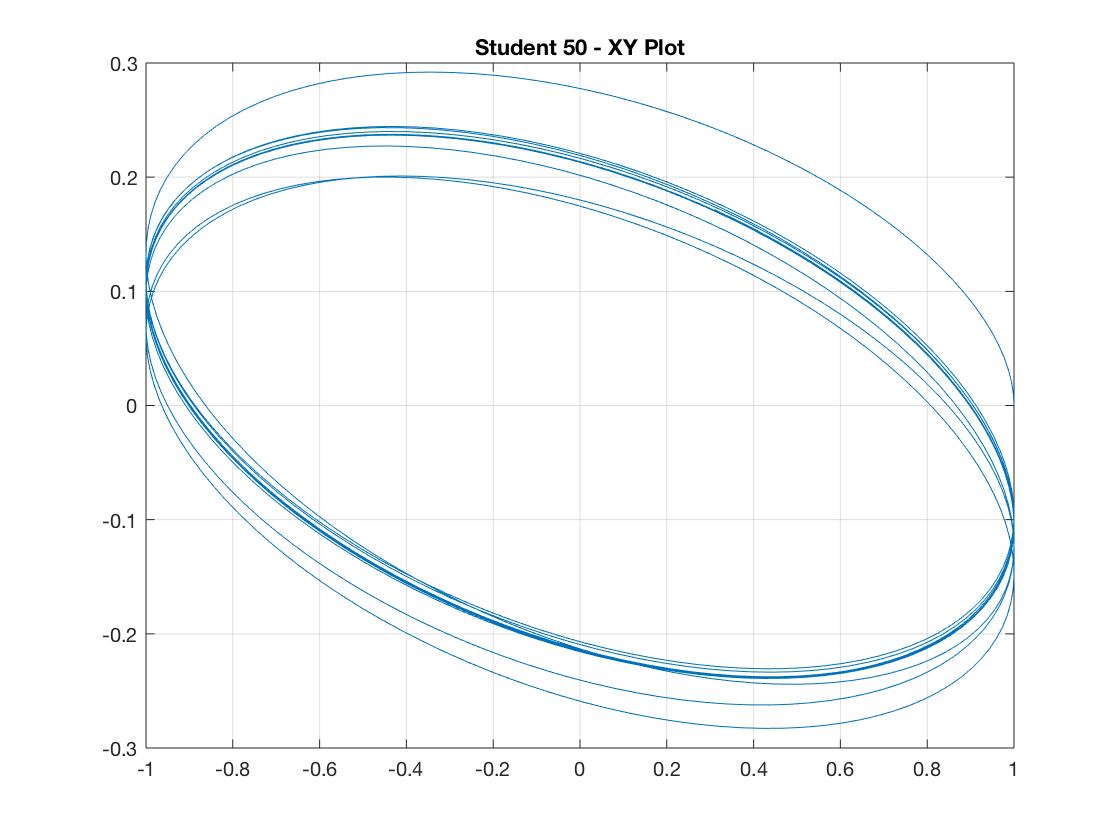

figure(3); clf;
% Plot here
plot(x,y)
title(sprintf('Student %d - XY Plot', Students.ID(1)));
grid on

- Find graphically the phase $\phi$ and magnitude $M$ at the specified frequency.

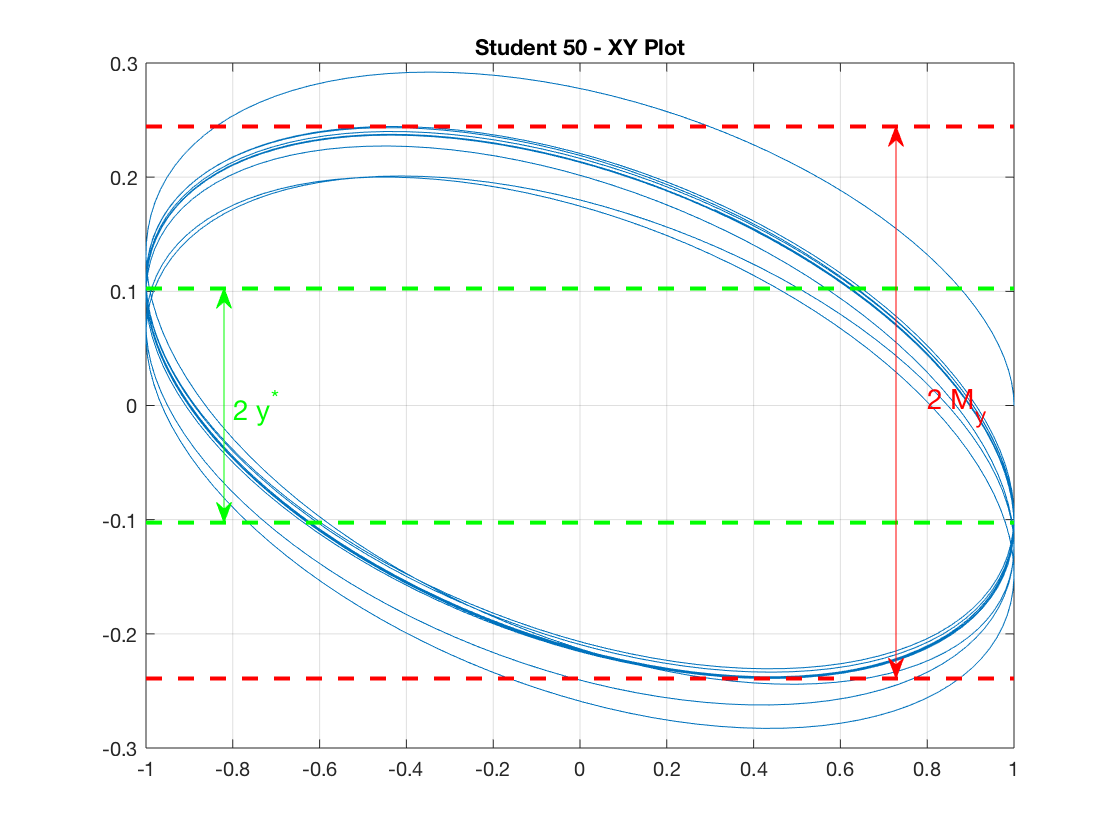

showMyAndYStar(t, x, y, Freq);

y_star = (0.1068 + 0.1056)/2;
My = (0.2523 + 0.2472)/2;
% Write phase and magnitude here
% we calculate phi by the Lissajous method 
phi = (acos(y_star/My) + pi) * 180/pi

phi = 244.8351

M = My

M = 0.2498

## **3. Identification of Qnet DC Motor Frequency Response**

To avoid the non-linear domain of the DC Motor at low voltage we will stimulate the DC Motor with offsetted cosine waves. We choose the following voltage signal:


$$v(t) = 4 + 2 \cos(2 \pi f t)$$


To send a cosine wave of frequency $f=0.5$ Hz to the Virtual Motor we do the following:

dt = 0.01; % sampling time
T = 15; % simulation duration
t = 0:dt:T; % define the time signal
vAmp = 2; % cosine amplitude
vOffset = 4; % voltage offset
Freq = 0.5; % frequency of cosine wave
Motor.reset();
Motor.input(vOffset + vAmp * cos(2*pi*Freq*t));
Motor.off();
Motor.save(Students, 'Lab08.Sinewave');
Motor.load('Lab08.Sinewave');

VirtualMotor::load::info: Recovering data collected by students: [260773785] .


For frequency analysis we are only interested at the steady-state response. We can retrieve the resulting angular velocity at steady state by:

delay = 5; % Ignore the first 5 seconds of experiment (transient response)
w = Motor.velocity(t >= delay); 
v = Motor.voltage(t >= delay);

The following shows a plot of the temporal response.

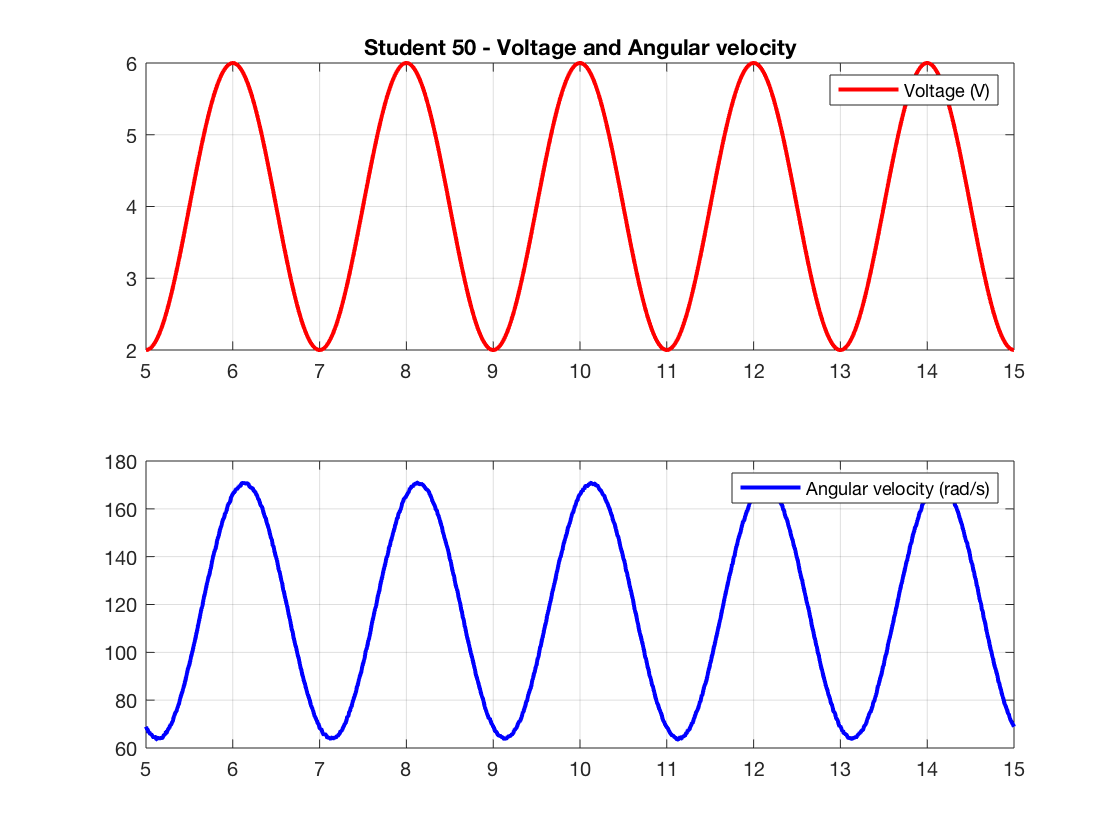

figure(4), clf;
subplot(2, 1, 1);
plot(t(t >= delay), v, 'r', 'linewidth', 2.0);
legend('Voltage (V)')
grid on
xlim([delay, T])
title(sprintf('Student %d - Voltage and Angular velocity', Students.ID(1)));
subplot(2, 1, 2);
plot(t(t >= delay), w, 'b', 'linewidth', 2.0);
legend('Angular velocity (rad/s)')
grid on
xlim([delay, T])

And the following shows the XY plot, which we can use to find $y^*$,  $M_y$ and $M_x$.

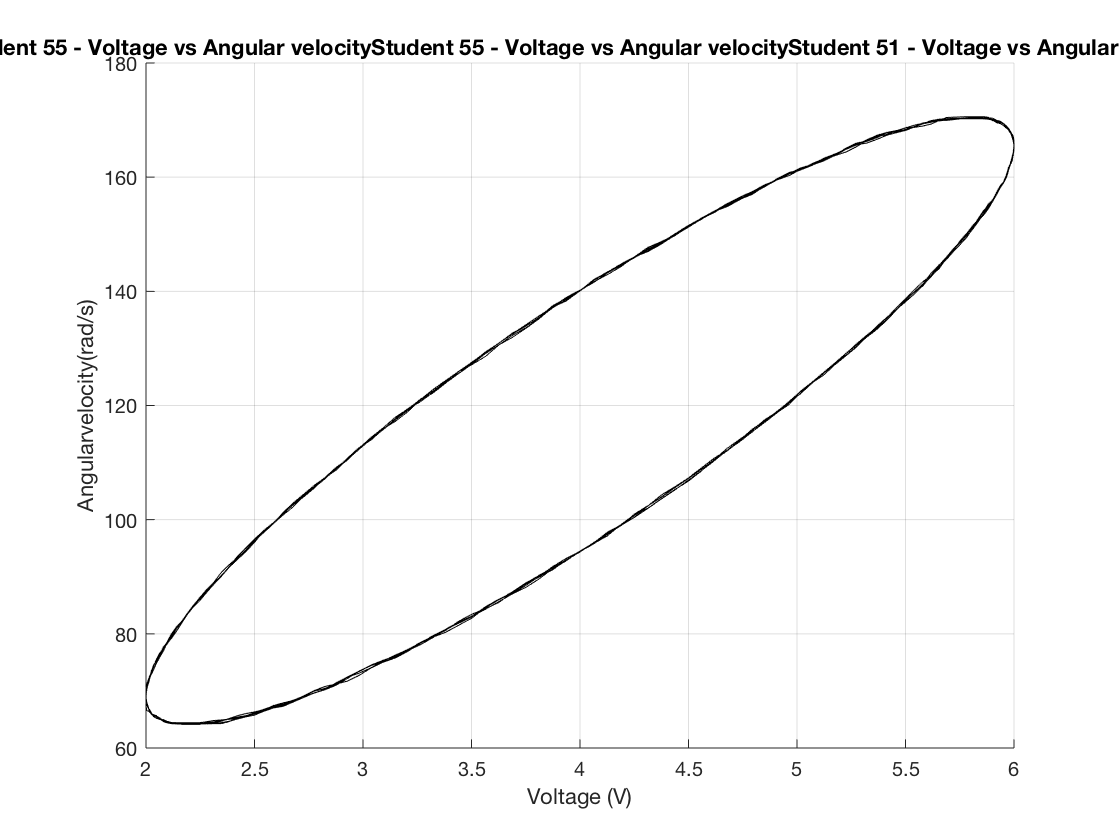

w_filter = medfilt1(w, 10, 'truncate'); % we can filter the noise if needed

figure(5), clf; hold on;
title(sprintf('Student %d - Voltage vs Angular velocity', Students.ID));
plot(v, w_filter, 'k');
grid on
xlabel('Voltage (V)')
ylabel('Angularvelocity(rad/s)')
xlim([2 6])

## *Question 3 (3.0 marks)*

Find the magnitude and phase of the transfer function of the Virtual Motor for the following frequencies.

FreqVect = [0.05, 0.1, 0.2, 0.4, 0.6, 0.8, 1.0, 1.2, 2.0, 4.0, 6.0];

Measure graphically the phase and magnitude for each frequency and put it here. Note: The size of MagnitudeDB and PhaseDeg is the same as FreqVect.

% Answer here
Freq = 6.0 

Freq = 6

%i get the frequency from freqvect

T = 2+5; 
t = 0:dt:T; 
% this is the duration time 
% 5 is the delay time which we identify before 

Motor.reset;
Motor.input(vOffset + vAmp * cos(2*pi*Freq*t));
Motor.off;

Motor.save(Students, ['Question3' num2str(Freq, '%3.2fHz')]);
% save the results

delay = 5;
v = Motor.voltage(t >= delay);
w = Motor.velocity(t >= delay);
% 5 is the delay as metioned in T

w_filter = medfilt1(w, 10, 'truncate');

figure(6); clf; set(gcf, 'Visible', 'on');
title(sprintf('Student %d - Voltage vs Angular velocity- Freq %3.2f Hz', Students.ID, Freq));
% name the title 

plot(v,w)
grid on
xlabel('Voltage (V)')
ylabel('Angular velocity (rad/s)')
%plot the diagram 

print(strrep(['XYPlot_Freq', num2str(Freq, '%03.2f'), 'Hz_Duration', num2str(T, '%02.1f'), 's'], '.', '_'), '-dpng');
%save the diagram 

MagnitudeDB = [28.434 28.555 28.375 28.084 27.822 26.86 26.19 25.27 22.32 17.39 13.58]

MagnitudeDB =    28.4340   28.5550   28.3750   28.0840   27.8220   26.8600   26.1900   25.2700   22.3200   17.3900   13.5800


PhaseDeg = [-11.00 -9.74 -14.223 -22.24 -37.4 -44.51 -53.66 -60.51 -54.97 -63.1 -33.647]

PhaseDeg =   -11.0000   -9.7400  -14.2230  -22.2400  -37.4000  -44.5100  -53.6600  -60.5100  -54.9700  -63.1000  -33.6470


% i calculate the maganitude of DB from Freq, y and My;
% phasedegree =y/My

## *Question 4 (1.0 mark)*

Draw the resulting Bode plot (Magnitude (dB) vs Frequency (Hz)) on a semilog plot and Phase (deg) vs Frequency (Hz) on a semilog plot). (Hint: help `semilogx`)

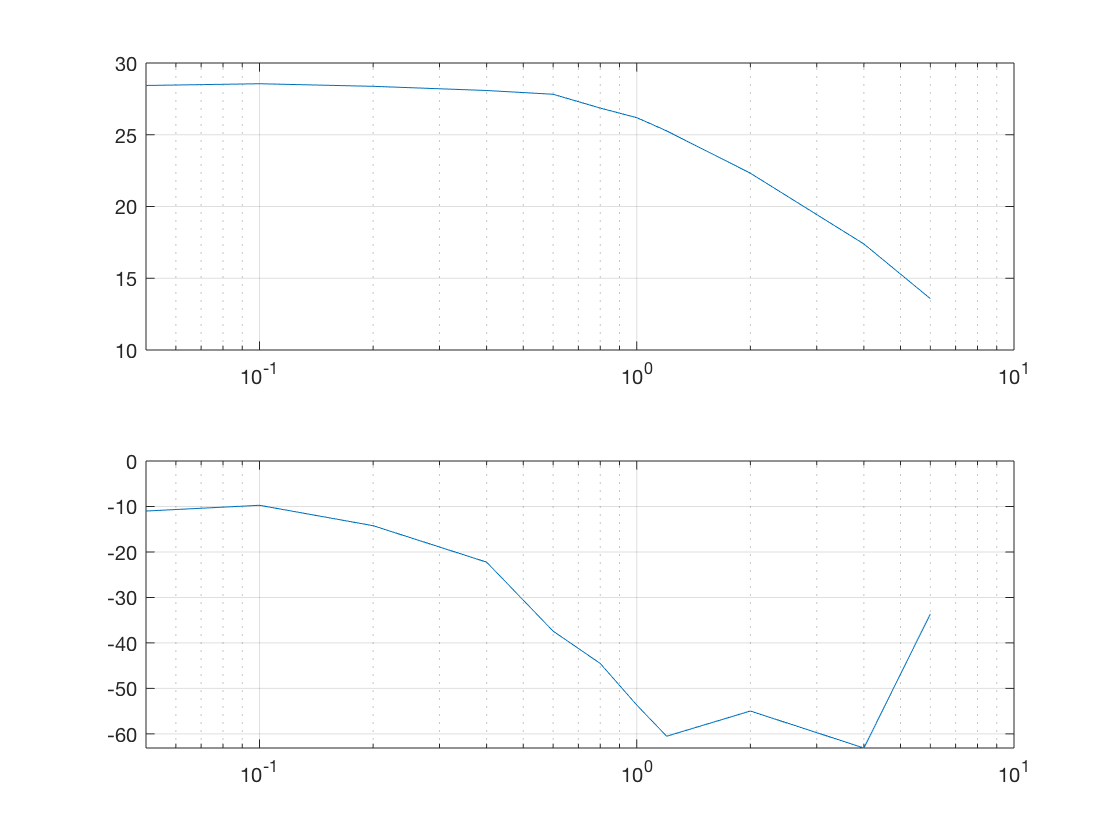

omega = 2 * pi * FreqVect;
figure(7); 
clf;
subplot(2, 1, 1)
semilogx(FreqVect,MagnitudeDB)

grid on
subplot(2, 1, 2)
semilogx(FreqVect,PhaseDeg)
% i draw the both maganitude and phase here 
grid on

## *Question 5 (1.0 mark)*

From the Bode plot, measure the DC gain.

DC_gain = 28.43

DC_gain = 28.4300

## *Question 6 (1.0 mark)*

From the Bode plot, measure the cut-off frequency (Frequency at which the magnitude drops by a factor of $-20\log_{10}\left(\displaystyle \frac{1}{\sqrt{2}}\right)=-3$ (dB) from the DC gain).

w_cutoff = 1.163*2*pi

w_cutoff = 7.3073

## *Question 7 (1.5 mark)*

For a first order system the transfer function is expressed by


$$H(s) = \displaystyle \frac{DC_{gain}}{1 + \displaystyle
\frac{s}{\omega_{cutoff}}}$$


- Write the transfer function of the identified DC Motor.

S = tf([DC_gain],[1/w_cutoff 1])


S =
 
     28.43
  ------------
  0.1368 s + 1
 
Continuous-time transfer function.



- Complete the code to superpose the experimental bode plot with the bode plot of the identified transfer function.

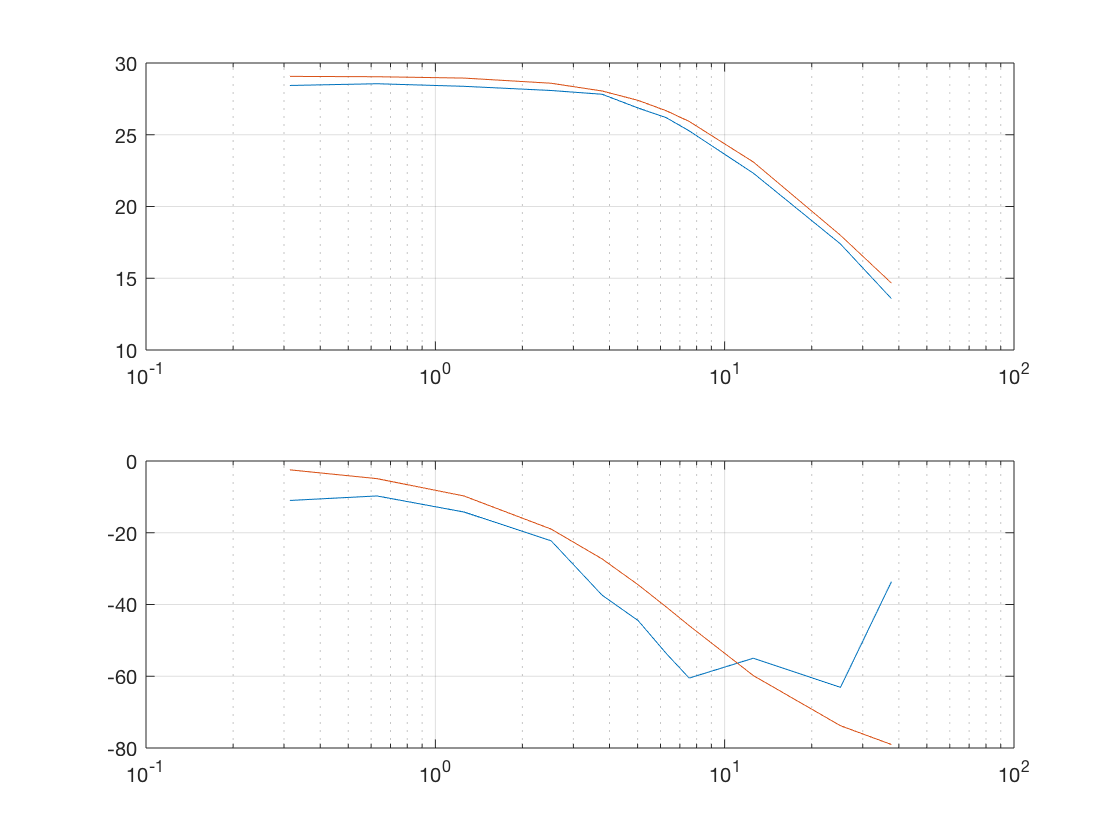

S_Freq(1,:) = (freqresp(S, omega, 'rad/s'));
S_MagnitudeDB = 20*log10(abs(H_Freq)); 
S_PhaseDeg = atan2(imag(S_Freq), real(S_Freq)) /pi * 180; 
% define the magnitude in db and phase in degrees
figure(8)
subplot(211)
semilogx(omega, [MagnitudeDB; S_MagnitudeDB])
grid on
subplot(212)
semilogx(omega, [PhaseDeg; S_PhaseDeg])
grid on

- How accurate is the point-by-point bode plot for high frequencies? Comment on your results.

% from the magnitude plot, the point-by-point bode plot for high frequency is pretty accutare 
% from the phase plot, it is not as accurate as the magnitude plot.

## **4. Useful Functions**

## *4.1 Customize the XY plot*

function showMyAndYStar(t, x, y, Freq)
max_y = max(y(t > round(5/Freq)));
max_x = max(x(t > round(5/Freq)));
min_y = min(y(t > round(5/Freq)));
min_x = min(x(t > round(5/Freq)));
star_y_1 = mean(y(t > round(5/Freq) & abs(x-max_x) < 0.05));
star_y_2 = mean(y(t > round(5/Freq) & abs(x-min_x) < 0.05));

gcf; hold on; axPos = get(gca, 'Position'); xMinMax = xlim; yMinMax = ylim;
plot([min_x, max_x], [max_y, max_y], '--r', 'linewidth', 2.0)
plot([min_x, max_x], [min_y, min_y], '--r', 'linewidth', 2.0)
annotation('doublearrow', [0.8, 0.8],...
    axPos(2)+(([max_y, min_y] - yMinMax(1)) / (yMinMax(2) - yMinMax(1)))*axPos(4), 'Color', 'red')
text(0.8, 0.0, '2 M_y', 'Color', 'red', 'FontSize', 14)
plot([min_x, max_x], [star_y_1, star_y_1], '--g', 'linewidth', 2.0)
plot([min_x, max_x], [star_y_2, star_y_2], '--g', 'linewidth', 2.0)
annotation('doublearrow', [0.2, 0.2],...
    axPos(2)+(([star_y_1, star_y_2] - yMinMax(1)) / (yMinMax(2) - yMinMax(1)))*axPos(4), 'Color', 'green')
text(-0.8, 0.0, '2 y^*', 'Color', 'green', 'FontSize', 14)
end